# MODELO DE DIAGNÓSTICO

close all; clc; clearvars;


## PREPROCESAMIENTO DE LA TABLA

T = readtable('Caracteristicas_MODELO.csv')

T = 1379×54 table
          image           Entropia_CR    Entropia_CV    Entropia_CA    Area_Copa    Diametro_Copa_MAX    Diametro_Copa_MIN    Area_Disco    Diametro_Disco_MAX    Diametro_Disco_MIN    C_DRatio    contrast_red    homogeneity_red    correlation_red    energy_red    contrast_green    homogeneity_green    correlation_green    energy_green    contrast_blue    homogeneity_blue    correlation_blue    energy_blue    mean_wavelet_1    mean_wavelet_2    mean_wavelet_3    mean_wavelet_4    mean_wavelet_5    

% filas_a_eliminar = T.C_DRatio == 0;
numeros_a_eliminar = {'0002','0003','0004','0026','0027','0028','0036','0037','0043','0057','0060','0062','0071','0075','0076','0080','0097','0122','0125','0137','0135','0152','0168','0173','0180','0197','0198','0213','0214','0216','0217','0219','0221','0237','0238','0256','0257','0269','0273','0289','0298','0306','0316','0319','0332','0334','0339','0340','0348','0351','0383','0389','0399','0422','0425','0438','0450','0473','0482','0496','0504','0518','0522','0561','0572','0590','0594','0595','0600','0613','0633','0636','0645','0671','0675','0708','0715','0742','0753','0759','0778','0779','0781','0783','0791','0792','0795','0800','0807','0816','0822','0827','0829','0830','0832','0842','0852','0869','0902','0904','0905','0913','0922','0925','0926','0927','0937','0938','0941','0950','0961','0969','0972','0977','0979','0989','0990','0991','1002','1027','1041','1045','1053','1061','1075','1076','1080','1082','1084','1088','1100','1105','1117','1133','1152','1151','1163','1164','1169','1174','1175','1191','1193','1200','1206','1208','1223','1232','1244','1251','1254','1263','1266','1268','1269','1270','1277','1288','1300','1305','1306','1307','1309','1314','1318','1330','1332','1340','1345','1350','1352','1356','1360','1372','1374','1378','1381','1382','1390','1391','1402','1406','1420','1427','1430','1443','1446','1455','1465','1466','1475','1502','1503','1507','1535','1532','1542','1545','1551','1561','1564','1567','0265','0755','0862','0976','1020','1098','1317','1482','1537','1568'};
Pocertaje_eliminado=round(size(numeros_a_eliminar,2)*100/height(T))

Pocertaje_eliminado = 15

% Paso 3: Convertir los números al formato de nombres de imágenes en la tabla
nombres_a_eliminar = strcat('image_', numeros_a_eliminar, '.jpg');

% Paso 4: Convertir cada nombre de imagen en una celda de cadena individual
nombres_a_eliminar = cellstr(nombres_a_eliminar);

% Paso 5: Encontrar las filas que contienen los nombres de imágenes a eliminar
filas_a_eliminar = ismember(T.image, nombres_a_eliminar);

% Paso 6: Eliminar las filas
T(filas_a_eliminar, :) = [];

% Paso 7: Guardar la tabla actualizada si es necesario
writetable(T, 'Caracteristicas_MODELO_actualizado.csv');


### **Desbalance de la variable glaucoma**

T=readtable("Caracteristicas_MODELO_actualizado.csv")

T = 1167×54 table
          image           Entropia_CR    Entropia_CV    Entropia_CA    Area_Copa    Diametro_Copa_MAX    Diametro_Copa_MIN    Area_Disco    Diametro_Disco_MAX    Diametro_Disco_MIN    C_DRatio    contrast_red    homogeneity_red    correlation_red    energy_red    contrast_green    homogeneity_green    correlation_green    energy_green    contrast_blue    homogeneity_blue    correlation_blue    energy_blue    mean_wavelet_1    mean_wavelet_2    mean_wavelet_3    mean_wavelet_4    mean_wavelet_5    

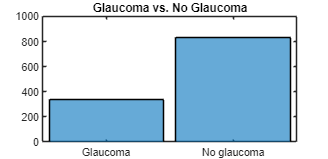


T.glaucoma = cellstr(num2str(T.glaucoma));

for i = 1:height(T)
    if T.glaucoma{i} == '1'
        T.glaucoma{i} = 'Glaucoma';
    elseif T.glaucoma{i} == '0'
        T.glaucoma{i} = 'No glaucoma';
    end
end


X = T{:, 2:end-1};
Y = T.glaucoma;

figure('Position', [0 0 350 170]);
histogram(categorical(Y))
title('Glaucoma vs. No Glaucoma')


class_no_glaucoma = T(T.glaucoma == "No glaucoma", :); % Clase mayoritaria
class_glaucoma = T(T.glaucoma == "Glaucoma", :); % Clase minoritaria

num_class_glaucoma = height(class_glaucoma); % Número de muestras en la clase minoritaria
random_indices = randperm(height(class_no_glaucoma), num_class_glaucoma); % Índices aleatorios
class_no_glaucoma_downsampled = class_no_glaucoma(random_indices, :); % Submuestrear la clase mayoritaria

% Guardar los índices de las filas eliminadas
indices_eliminados = setdiff(1:height(class_no_glaucoma), random_indices);
% Guardar los índices eliminados en un archivo CSV para referencia
writematrix(indices_eliminados', 'indices_eliminados.csv');

% Paso 5: Combinar las clases
balanced_data = [class_no_glaucoma_downsampled; class_glaucoma];
balanced_data = balanced_data(randperm(height(balanced_data)), :); % Mezclar aleatoriamente

writetable(balanced_data, 'Caracteristicas_BALANCED_MODELO.csv');

% Paso 6: Verificar el balance de clases después del submuestreo
disp('Número de muestras de cada clase (balanceado):');

Número de muestras de cada clase (balanceado):


disp(['Glaucoma: ', num2str(sum(balanced_data.glaucoma == "Glaucoma"))]);

Glaucoma: 337


disp(['No glaucoma: ', num2str(sum(balanced_data.glaucoma == "No glaucoma"))]);

No glaucoma: 337



prueba=sortrows(balanced_data.image(balanced_data.glaucoma=="Glaucoma"))

prueba = 337×1 cell array
    {'image_0005.jpg'}
    {'image_0010.jpg'}
    {'image_0016.jpg'}
    {'image_0029.jpg'}
    {'image_0032.jpg'}
    {'image_0034.jpg'}
    {'image_0044.jpg'}
    {'image_0047.jpg'}
    {'image_0051.jpg'}
    {'image_0058.jpg'}
    {'image_0059.jpg'}
    {'image_0070.jpg'}
    {'image_0072.jpg'}
    {'image_0079.jpg'}
    {'image_0084.jpg'}
    {'image_0086.jpg'}
    {'image_0090.jpg'}
    {'image_0091.jpg'}
    {'image_0092.jpg'}
    {'image_0093.jpg'}
    {'image_0102.jpg'}
    {'image_0103.jpg'}
    {'image_0106.jpg'}
    {'image_0107.jpg'}
    {'image_0110.jpg'}
    {'image_0119.jpg'}
    {'image_0121.jpg'}
    {'image_0128.jpg'}
    {'image_0141.jpg'}
    {'image_0146.jpg'}


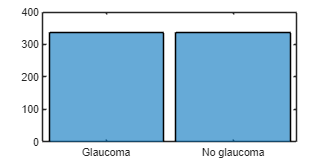


X = balanced_data{:, 2:end-1}; % Características (ajusta según las columnas de tus datos)
Y = balanced_data.glaucoma; % Etiquetas
histogram(categorical(Y))

## CORRELACIÓN DE VARIABLES

T=readtable('Caracteristicas_BALANCED_MODELO.csv')

T = 674×54 table
          image           Entropia_CR    Entropia_CV    Entropia_CA    Area_Copa    Diametro_Copa_MAX    Diametro_Copa_MIN    Area_Disco    Diametro_Disco_MAX    Diametro_Disco_MIN    C_DRatio    contrast_red    homogeneity_red    correlation_red    energy_red    contrast_green    homogeneity_green    correlation_green    energy_green    contrast_blue    homogeneity_blue    correlation_blue    energy_blue    mean_wavelet_1    mean_wavelet_2    mean_wavelet_3    mean_wavelet_4    mean_wavelet_5    

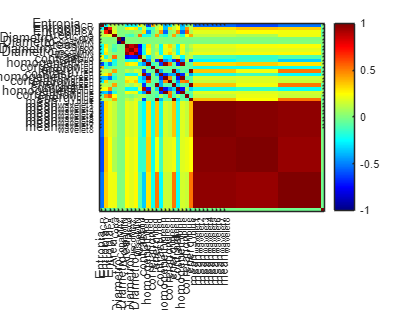

 for i = 1:height(T)
        if strcmp(T.glaucoma{i}, 'Glaucoma')
            T.glaucoma{i} = 1;
        elseif strcmp(T.glaucoma{i}, 'No glaucoma')
            T.glaucoma{i} = 0;
        end
    end
    % Convertir la columna a un array numérico
    T.glaucoma = cell2mat(T.glaucoma);
    
variables = T.Properties.VariableNames;
X = T{:, 2:end};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values
figure;
imagesc(R); clim([-1 1]);
xticks(1:30);
xticklabels(variables(:,2:end));
yticks(1:30);
yticklabels(variables(:,2:end));
colormap(jet); colorbar;

variables = T.Properties.VariableNames;

## ENTRENAMIENTO DE MODELOS

rng(4);

T=readtable('Caracteristicas_BALANCED_MODELO.csv');
T.image=[];
% T.glaucoma = cellstr(num2str(T.glaucoma));
% 
% for i = 1:height(T)
%     if T.glaucoma{i} == '1'
%         T.glaucoma{i} = 'Glaucoma';
%     elseif T.glaucoma{i} == '0'
%         T.glaucoma{i} = 'No glaucoma';
%     end
% end

### División de data

p = 0.2;
cv_out = cvpartition(T.glaucoma, 'HoldOut', p, 'Stratify', true);
T_train = T(cv_out.training, :);
T_test  = T(cv_out.test, :);

k = 10;
cv_in = cvpartition(T_train.glaucoma, 'KFold', k, 'Stratify', true);

### MODELO-KNN

% Create cross-validated KNN model
mdl_knn = fitcknn(T_train, 'glaucoma', 'NumNeighbors', 3, 'CVPartition', cv_in);

% mdl_knn = fitcknn(T_train, 'quality', 'NumNeighbors', 3, 'CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_knn); % This row will print the mean error value. 

Estimate test performance

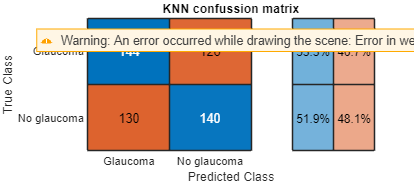

% mdl_loss = kfoldLoss(mdl_knn, 'Mode', 'Individual'); %This row will compute the Loss for each Cross-Validation fold. This is interesting for the final comparisons. 
Y_pred = kfoldPredict(mdl_knn);
accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
results = table;
results = [results; table("Knn", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(T_train.glaucoma, Y_pred, 'RowSummary','row-normalized')
title('KNN confussion matrix');

## Entrenamiento de modelo-Classification Trees

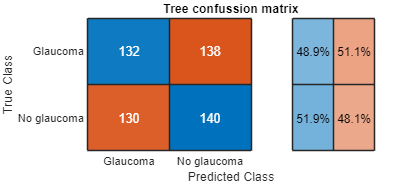

mdl_tree = fitctree(T_train, 'glaucoma', 'CVPartition', cv_in);

mdl_loss = kfoldLoss(mdl_tree);

Y_pred = kfoldPredict(mdl_tree);

accuracy = sum(strcmp(Y_pred,T_train.glaucoma)) / height(T_train);
results = [results; table("Tree", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(T_train.glaucoma, Y_pred, 'RowSummary','row-normalized')
title('Tree confussion matrix');

## Entrenamiento de modelo-Naive Bayes

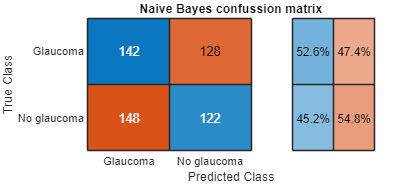

mdl_NB = fitcnb(T_train, 'glaucoma','CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_NB);
Y_pred = kfoldPredict(mdl_NB);
accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
results = [results; table("Naive_bayes", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];
figure('Position', [0 0 450 200]);
confusionchart(T_train.glaucoma, Y_pred, 'RowSummary','row-normalized')
title('Naive Bayes confussion matrix');

## Entrenamiento de modelo-SVM

mdl_svm = fitcsvm(T_train, 'glaucoma','CVPartition',cv_in);
mdl_loss = kfoldLoss(mdl_svm);
Y_pred = kfoldPredict(mdl_svm);

accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
results = [results; table("SVM", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

results

results = 4×3 table
        model         loss      accuracy
    _____________    _______    ________

    "Knn"            0.47407    0.52593 
    "Tree"            0.4963     0.5037 
    "Naive_bayes"    0.51111    0.48889 
    "SVM"                0.5        0.5 


[~, best_model] = max(results.accuracy);
results(best_model, :)

ans = 1×3 table
    model     loss      accuracy
    _____    _______    ________

    "Knn"    0.47407    0.52593 


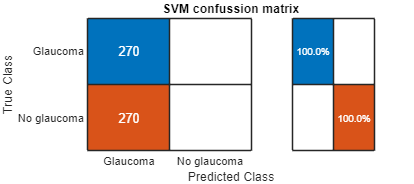


figure('Position', [0 0 450 200]);
confusionchart(T_train.glaucoma, Y_pred, 'RowSummary','row-normalized')
title('SVM confussion matrix');

## Final model testing

mdl_final = fitcecoc(T_train, 'glaucoma');
Y_pred = predict(mdl_final, T_test);

loss_final = loss(mdl_final, T_test)

loss_final = 0.5000

accuracy_final = sum(strcmp(Y_pred, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final = 0.5000

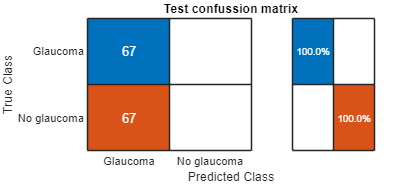



figure('Position', [0 0 450 200]);
confusionchart(T_test.glaucoma, Y_pred, 'RowSummary','row-normalized')
title('Test confussion matrix');

## REENTRENAMIENTO CON LOS ELIMINADOS

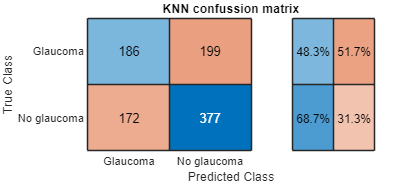

% Leer los índices eliminados desde el archivo CSV
indices_eliminados = readmatrix('indices_eliminados.csv');
T_original = readtable("Caracteristicas_MODELO_actualizado.csv");

% Recuperar las imágenes eliminadas de "No glaucoma"
imagenes_recuperadas = T_original(indices_eliminados, :);

balanced_data = readtable('Caracteristicas_BALANCED_MODELO.csv');

% Convertir la columna glaucoma a numérico si es necesario
for i = 1:height(balanced_data)
    if strcmp(balanced_data.glaucoma{i}, 'Glaucoma')
        balanced_data.glaucoma{i} = 1;
    elseif strcmp(balanced_data.glaucoma{i}, 'No glaucoma')
        balanced_data.glaucoma{i} = 0;
    end
end
balanced_data.glaucoma = cell2mat(balanced_data.glaucoma);

% Combinar las imágenes recuperadas con los datos balanceados
rng(4);
updated_data = [balanced_data; imagenes_recuperadas];
updated_data.image=[];

updated_data.glaucoma = cellstr(num2str(updated_data.glaucoma));

for i = 1:height(updated_data)
    if updated_data.glaucoma{i} == '1'
        updated_data.glaucoma{i} = 'Glaucoma';
    elseif updated_data.glaucoma{i} == '0'
        updated_data.glaucoma{i} = 'No glaucoma';
    end
end

% División de data
p = 0.2;
cv_out = cvpartition(updated_data.glaucoma, 'HoldOut', p, 'Stratify', true);
T_train = updated_data(cv_out.training, :);
T_test  = updated_data(cv_out.test, :);

k = 10;
cv_in = cvpartition(T_train.glaucoma, 'KFold', k, 'Stratify', true);

% Reentrenar y evaluar los modelos

% KNN
mdl_knn = fitcknn(T_train, 'glaucoma', 'NumNeighbors', 3, 'CVPartition', cv_in);
mdl_loss_knn = kfoldLoss(mdl_knn);
Y_pred_knn = kfoldPredict(mdl_knn);
accuracy_knn = sum(strcmp(Y_pred_knn, T_train.glaucoma)) / height(T_train);

figure('Position', [0 0 450 200]);
confusionchart(T_train.glaucoma, Y_pred_knn, 'RowSummary','row-normalized')
title('KNN confussion matrix');

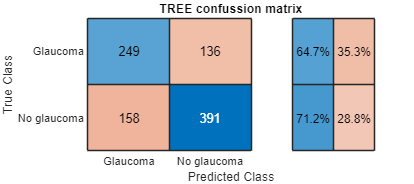


% Classification Tree
mdl_tree = fitctree(T_train, 'glaucoma', 'CVPartition', cv_in);
mdl_loss_tree = kfoldLoss(mdl_tree);
Y_pred_tree = kfoldPredict(mdl_tree);
accuracy_tree = sum(strcmp(Y_pred_tree, T_train.glaucoma)) / height(T_train);

figure('Position', [0 0 450 200]);
confusionchart(T_train.glaucoma, Y_pred_tree, 'RowSummary','row-normalized')
title('TREE confussion matrix');

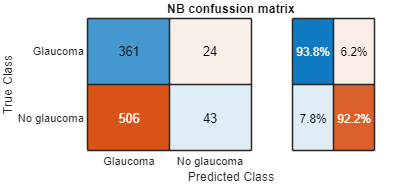


% Naive Bayes
mdl_NB = fitcnb(T_train, 'glaucoma', 'CVPartition', cv_in);
mdl_loss_NB = kfoldLoss(mdl_NB);
Y_pred_NB = kfoldPredict(mdl_NB);
accuracy_NB = sum(strcmp(Y_pred_NB, T_train.glaucoma)) / height(T_train);

figure('Position', [0 0 450 200]);
confusionchart(T_train.glaucoma, Y_pred_NB, 'RowSummary','row-normalized')
title('NB confussion matrix');

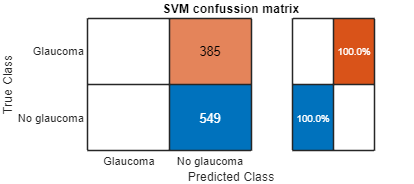


% SVM
mdl_svm = fitcsvm(T_train, 'glaucoma', 'CVPartition', cv_in);
mdl_loss_svm = kfoldLoss(mdl_svm);
Y_pred_svm = kfoldPredict(mdl_svm);
accuracy_svm = sum(strcmp(Y_pred_svm, T_train.glaucoma)) / height(T_train);

figure('Position', [0 0 450 200]);
confusionchart(T_train.glaucoma, Y_pred_svm, 'RowSummary','row-normalized')
title('SVM confussion matrix');


% Resultados
results = table;
results = [results; table("KNN", mdl_loss_knn, accuracy_knn, 'VariableNames', {'Model', 'Loss', 'Accuracy'})];
results = [results; table("Tree", mdl_loss_tree, accuracy_tree, 'VariableNames', {'Model', 'Loss', 'Accuracy'})];
results = [results; table("Naive Bayes", mdl_loss_NB, accuracy_NB, 'VariableNames', {'Model', 'Loss', 'Accuracy'})];
results = [results; table("SVM", mdl_loss_svm, accuracy_svm, 'VariableNames', {'Model', 'Loss', 'Accuracy'})];

disp(results);

        Model         Loss      Accuracy
    _____________    _______    ________

    "KNN"            0.39722    0.60278 
    "Tree"           0.31478    0.68522 
    "Naive Bayes"    0.56745    0.43255 
    "SVM"            0.41221    0.58779 




% Test final con el mejor modelo
mdl_final = fitcknn(T_train, 'glaucoma');
Y_pred_final = predict(mdl_final, T_test);
loss_final = loss(mdl_final, T_test);
accuracy_final = sum(strcmp(Y_pred_final, T_test.glaucoma)) / height(T_test);

disp(['Loss final: ', num2str(loss_final)]);

Loss final: 0.32618


disp(['Accuracy final: ', num2str(accuracy_final)]);

Accuracy final: 0.67382


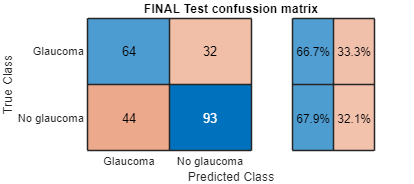


figure('Position', [0 0 450 200]);
confusionchart(T_test.glaucoma, Y_pred_final, 'RowSummary','row-normalized')
title('FINAL Test confussion matrix');